pointNum = 1000;
groupDistance = 10;

userID = linspace(1, pointNum, pointNum);
latitude = (rand(1, pointNum)*2-1) * 180;
longitude = (rand(1, pointNum)*2-1) * 90;
needs = cell(1, pointNum);
maxNeeds = 10;
for i = 1:pointNum
    needNum = randi(maxNeeds);
    for j = 1:needNum
        percentage = 0.25;
        chance = rand;
        if (chance < percentage)
            needs{i}(end+1) = j;
        end
    end
    if (isempty(needs{i}))
        needs{i}(end+1) = randi([1, needNum]);
    end
%     needs{i} = mat2str(needs{i});
end
age = randi([1 80], 1, pointNum);
gender = string.empty(0, pointNum);
for i = 1:pointNum
    percentage = 0.5;
    chance = rand;
    if (chance < percentage)
        gender(i) = "Male";
    else
        gender(i) = "Female";
    end
end

userID = userID';
latitude = latitude';
longitude = longitude';
needs = needs';
age = age';
gender = gender';

X = [longitude latitude];

clear table;
output = table(userID, X(:, 1), X(:, 2), needs, age, gender)

output = 1000×6 table
    userID     Var2       Var3         needs       age     gender 
    ______    _______    _______    ___________    ___    ________

       1       -60.79    -134.83    {[    1 2]}    17     "Female"
       2       69.249     43.186    {[      5]}    56     "Male"  
       3       60.201    -46.674    {[1 2 3 9]}    62     "Male"  
       4       -74.68    -12.161    {[    2 4]}    67     "Female"
       5       82.615    -4.3424    {[      2]}    54     "Female"
       6      -58.042     111.88    {[      3]}    31     "Female"
       7      -25.133     107.79    {[      3]}    78     "Male"  
       8       7.8868     21.369    {[      2]}    76     "Male"  
       9       -8.871    -1.7861    {[    1 4]}    50     "Male"  
      10       1.7279     -140.2    


% geoscatter(X(:, 2), X(:, 1), 50, "r.")
% geolimits([-90 90],[180 -180])

% rng default;  % For reproducibility

% Y = pdist(X);
% Y = squareform(Y);
% Z = linkage(Y);
% T = cluster(Z,'cutoff', groupDistance,'Criterion','distance');
% 
% clusterNum = length(unique(T));
% clusterArray = cell(clusterNum, 1);
% for i = 1:size(T, 1)
%     clusterArray{T(i)}(end+1) = i;
% end
% 
% clusterInfo = randi([0 0], clusterNum, 3);
% for i = 1:clusterNum
%     currArr = randi([0 0], size(clusterArray{i}, 2), 2);
%     for j = 1:size(clusterArray{i}, 2)
%         currID = clusterArray{i}(j);
% 
%         currArr(j, 1) = longitude(currID);
%         currArr(j, 2) = latitude(currID);
%     end
%     maxLong = (max(currArr(:, 1)) + min((currArr(:, 1)))) / 2;
%     maxLat = (max(currArr(:, 2)) + min((currArr(:, 2)))) / 2;
%     clusterInfo(i, 1) = maxLong;
%     clusterInfo(i, 2) = maxLat;
%     clusterInfo(i, 3) = max(abs(max(currArr(:, 1)) - min((currArr(:, 1)))), abs(max(currArr(:, 2)) - min((currArr(:, 2)))));
%     geoscatter(clusterInfo(i, 2), clusterInfo(i, 1), clusterInfo(i, 3)+8, "bo")
% end
% 
% clusterInfo

opts = statset('Display','final');
[idx, c, sumd, k] = kmeans_opt(X);
clusterNum = k;
iterations = 100;
% gscatter(X(:, 2),X(:, 1),idx)
% set(gca, 'XLim', [-180 180], 'YLim', [-90 90]);
geoscatter(X(:, 1), X(:, 2), 25, "r.")
geolimits([-90 90], [-180 180]);
hold on;
voronoi(c(:, 1), c(:, 2));
clusterInfo = cell(k, 4);
for i = 1:pointNum
    clusterInfo{idx(i)}(end+1) = i;
end

for i = 1:clusterNum
    clusterInfo{i, 2} = randi([0 0], 1, maxNeeds);

    ageArr = randi([0 0], size(clusterInfo{i, 1}, 2), 1);
    childCount = 0;
    adultCount = 0;
    elderCount = 0;

    maleCount = 0;
    femaleCount = 0;

    needsCount = 0;

    for j = 1:size(clusterInfo{i, 1}, 2)
        currID = clusterInfo{i, 1}(j);

        for k = 1:size(needs{currID}, 2)
            currNeed = needs{currID}(k);
            needsCount = needsCount + 1;
            clusterInfo{i, 2}(currNeed) = clusterInfo{i, 2}(currNeed) + 1;
        end

        ageArr(j) = age(currID);
        if (ageArr(j) < 18)
            childCount = childCount + 1;
        elseif (ageArr(j) >= 18 && ageArr(j) < 65)
            adultCount = adultCount + 1;
        else
            elderCount = elderCount + 1;
        end
        
        if (gender(currID) == "Male")
            maleCount = maleCount + 1;
        else
            femaleCount = femaleCount + 1;
        end
    end
    ageAvg = ceil(sum(ageArr) / size(ageArr, 1));
    clusterInfo{i, 3} = "Children: " + childCount + ", Adults: " + adultCount + ", Elders: " + elderCount + ", Average Age: " + ageAvg;
    
    genderMaj = "Equal Ratio";
    if (maleCount > femaleCount)
        genderMaj = "Male Majority";
    elseif (femaleCount > maleCount)
        genderMaj = "Female Majority";
    end
    clusterInfo{i, 4} = "Males: " + maleCount + ", Females: " + femaleCount + ", Majority: " + genderMaj;

%     scatter(c(i, 2), c(i, 1), 100, "k+")
    geoscatter(c(i, 1), c(i, 2), 100, "k+")
    textLabel = size(clusterInfo{i}, 2) + " Users" + newline + needsCount + " Needs";
    text(c(i, 1), c(i, 2)+10, textLabel, 'FontSize', 8);
end

finalResult = cell2table(clusterInfo, "VariableNames",["Users" "Total Needs" "Age Info" "Gender Info"])

finalResult = 13×4 table
                                                                                                                                                                                                 Users                                                                                                                                                                                                  Total Needs                           Age Info                                                Gender Info                    
    _________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

for i = 1:clusterNum
    clusterInfo{i} = mat2str(clusterInfo{i});
    clusterInfo{i, 2} = mat2str(clusterInfo{i, 2});
end
finalResult = cell2table(clusterInfo, "VariableNames",["Users" "Total Needs" "Age Info" "Gender Info"])

finalResult = 13×4 table
                                                                                                                                                                                                  Users                                                                                                                                                                                                              Total Needs                                      Age Info                                                Gender Info                    
    _________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

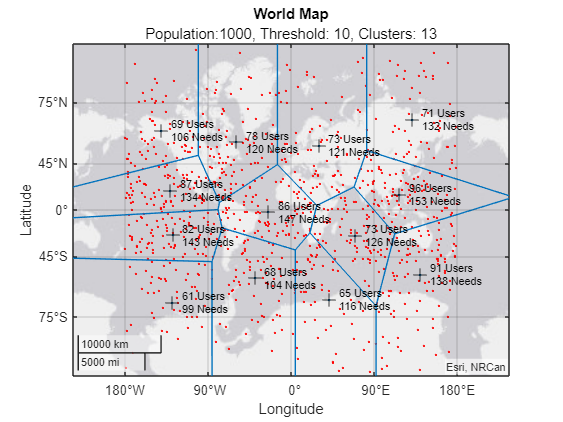


title("World Map");
subtitle("Population:" + pointNum + ", Threshold: " + groupDistance + ", Clusters: " + clusterNum);

% xlabel("Longitude");
% ylabel("Latitude");
legend('off');

%writetable(output,"Data.csv");
writetable(finalResult, "Result.csv");